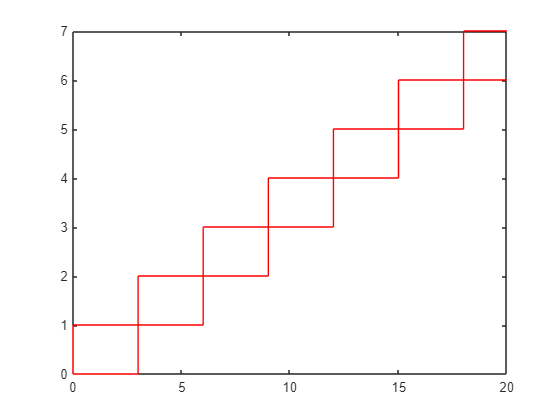

% EVENT STREAMS
a_in = rtcpjd(3, 0, 0);
rtcplot(a_in, 'r', 20);

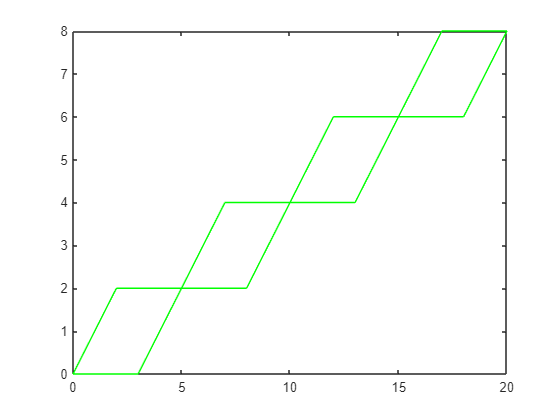


% RESEOURCE MODELS
b_in = rtctdma(2, 5, 1); % slot, cycle/period, bandwidth
rtcplot(b_in, 'g', 20);

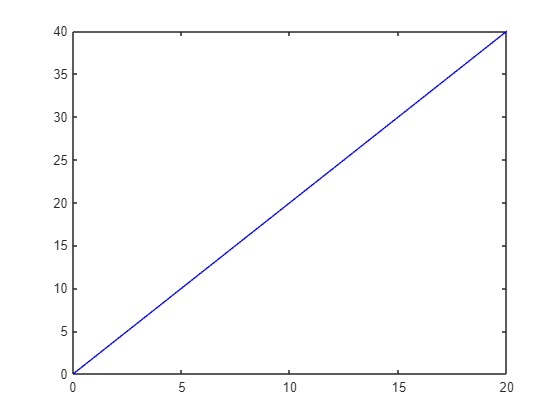

b2_in = rtcfs(2);
rtcplot(b2_in, 'b', 20);


% ONE GPC
ed1   = 1; % execution resource demand
[a_out b_out del buf] = rtcgpc(a_in, b_in, ed1);
disp(['delay = ',num2str(del), ';  buffer = ',num2str(buf)]);

delay = 4;  buffer = 2


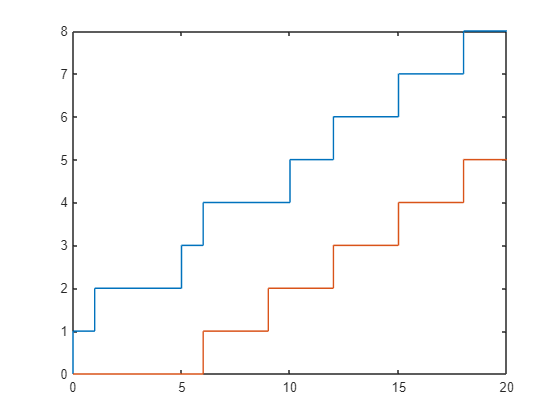

rtcplot(a_out, 20)

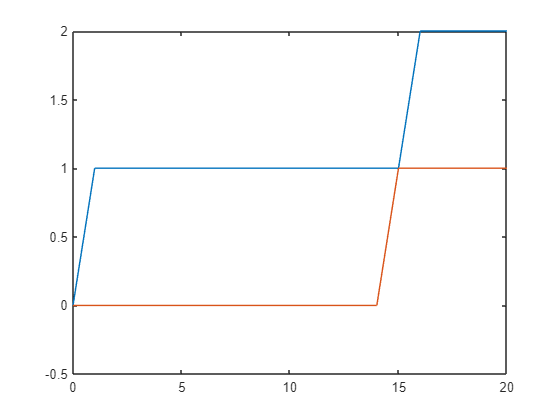

rtcplot(b_out, 20);


ed2 = 1;
[a_out_out b2_out del2 buf2] = rtcgpc(a_out, b2_in, ed2);
disp(['delay = ',num2str(del2), ';  buffer = ',num2str(buf2)]);

delay = 0.5;  buffer = 1


rtcplot(a_out_out, 20)

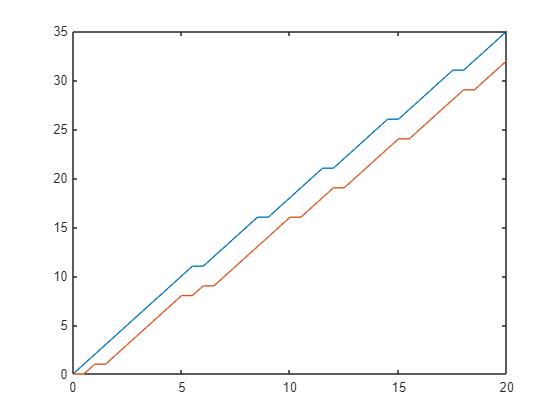

rtcplot(b2_out, 20);


% TODAL MAX END2END DELAY
disp(['del1 + del2 = ', num2str(del+del2)]);

del1 + del2 = 4.5


% more accurate and tighter bounds:
del_e2e = rtcdel(a_in, b_in, ed1, b2_in, ed2);
disp(['del_e2e = ', num2str(del_e2e)]);

del_e2e = 4.5



% TOTAL MAX BUFFER REQUIREMENTS
% maximum buffer space that is necessary
% when an event stream is processed on n consecutive GPC's
% if their input queues all access the same SHARED memory
disp(['buf1 + buf2 = ', num2str(buf+buf2)]);

buf1 + buf2 = 3


% tighter bound:
buf_sha =  rtcbuf(a_in, b_in, ed1, b2_in, ed2);
disp(['buf_sha = ', num2str(buf_sha)]);

buf_sha = 2


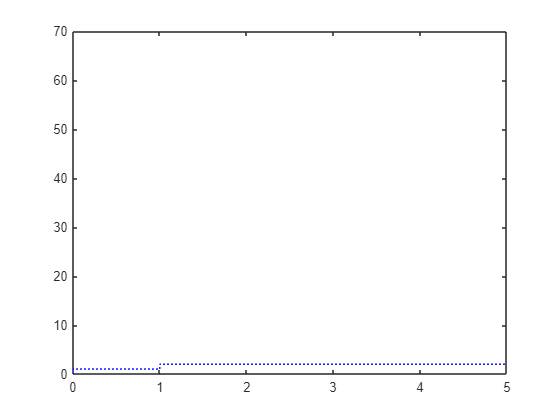


% CURVES
% au = rtccurve([[0 0 0]], 32, 32, inf);
% bu = rtccurve([[0 1 0];[1 2 0]], 0, 5, 2);
% rtcplot(au, 'r--', bu, 'b:', [0 5 0 70]);

%fm = ([plots], startingHeight, period, yOffsetPerPeriod);

% OBTAINING VALUES
%y = rtcvalue(g,5,1);
% disp(['y = ', num2str(y)]);
% g at position x=5+epsilon (or -epsilon if (g,5,-1))
% epsilon needed if g is not continuit at x=5

% CALCULATIONS
% f +/- g pointwise: h = rtcplus(f, g);
% f and g can here both also be scalars (e.g. 4)
% max/min of two curves: h = rtcmax(f,g)
% divide/times f pointwise: h = rtcdivide(f, scalar)

% pointwise (interval length = 1) h = rtcceil/rtcfloor(f)

% MIN MAX ALGEBRA
% h = rtcmin(de)conv(f,g)
% analoque for max
% also defined for curev and scalar

% MAYBE USE IN PAPER?!
% d = rtcploth(f, g) plots max horizontal distance between f and g
% analogue with rtcplotv for vertical distance
% plot bounds of a periodic curve: rtcplotbounds(f)

% au = rtccurve([[0 1 0];[2 2 0];[4 3 0];[8 4 0];[14 5 0]]);
% bl = rtccurve([[0 0 0];[6 0 0.3];[12 1.8 0.8]]);
% rtcplot(au, 'r--', bl, 'b--', 20);
% dh = rtcploth(au, bl);
% dv = rtcplotv(au, bl);